# **Chapter20 mini quiz (Lec14) [ALL CORRECT]**

## Q1

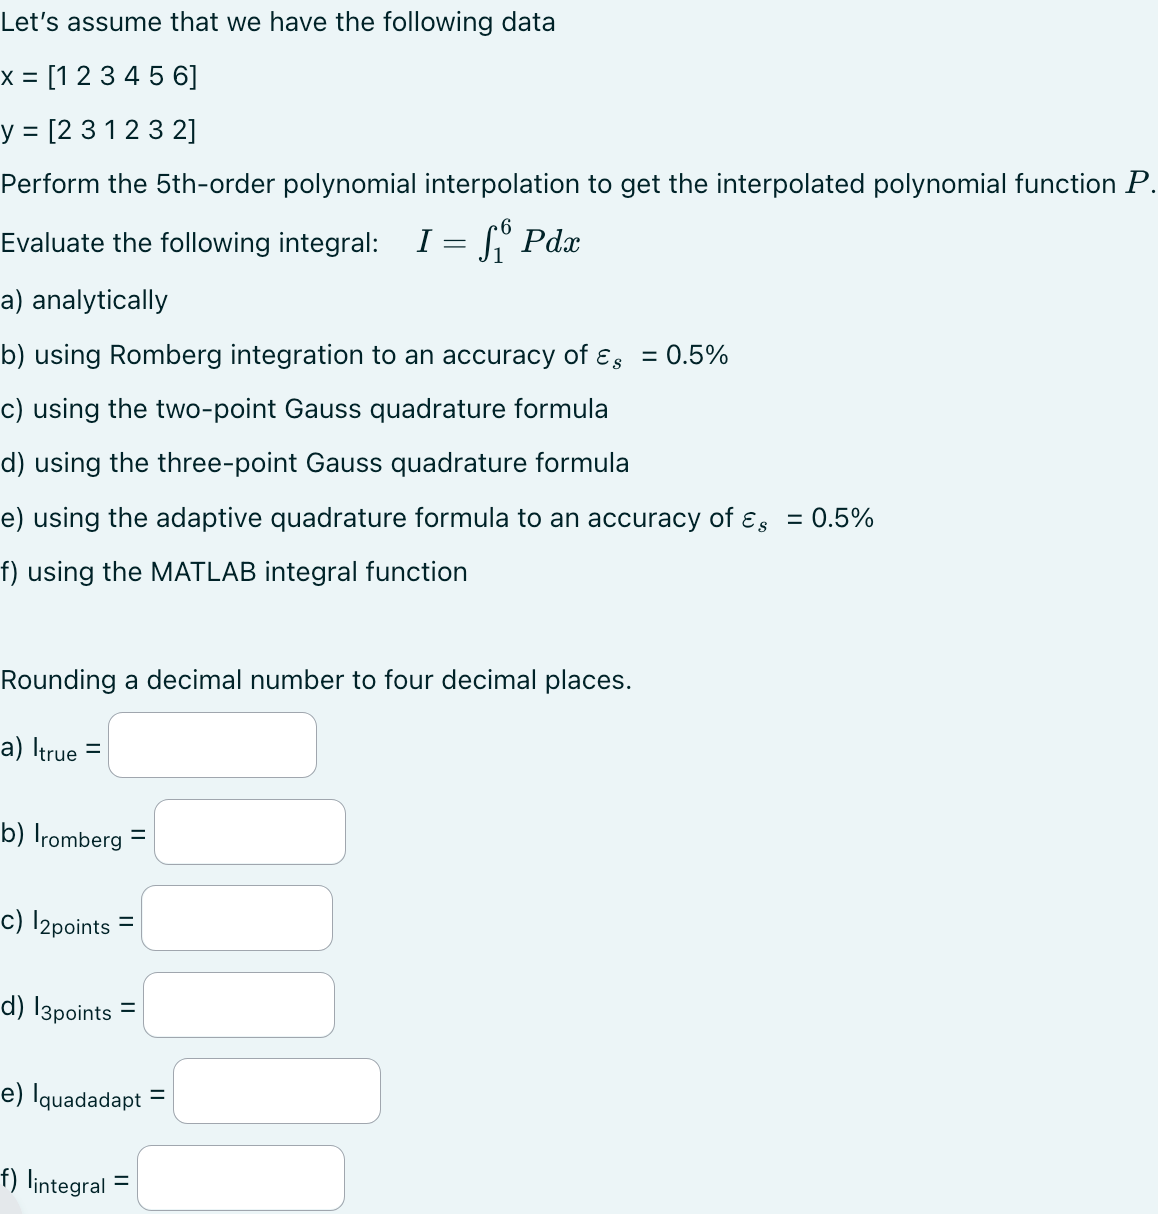

Data and the function

x = [1 2 3 4 5 6];
y = [2 3 1 2 3 2];

p5 = polyfit(x, y, 5) % recall that this is just coefficients

p5 =     0.0833   -1.6250   11.8333  -39.3750   58.0833  -27.0000


% NOTE: Since we have to use the Romberg function which requires an actual
% function as one of its arguments, we have to map the coefficients from
% the `polyfit` as a function. However, when doing usual integration, we
% can directly use those coefficients.
f = @(x) ...
    p5(1).*x.^5 + ...
    p5(2).*x.^4 + ...
    p5(3).*x.^3 + ...
    p5(4).*x.^2 + ...
    p5(5).*x.^1 + ...
    p5(6);

% PLOTTING
figure
plot(x, y, 'mo', 'LineWidth', 2)
xx = 1 : 0.01 : 6

xx =     1.0000    1.0100    1.0200    1.0300    1.0400    1.0500    1.0600    1.0700    1.0800    1.0900    1.1000    1.1100    1.1200    1.1300    1.1400    1.1500    1.1600    1.1700    1.1800    1.1900    1.2000    1.2100    1.2200    1.2300    1.2400    1.2500    1.2600    1.2700    1.2800    1.2900    1.3000    1.3100    1.3200    1.3300    1.3400    1.3500    1.3600    1.3700    1.3800    1.3900    1.4000    1.4100    1.4200    1.4300    1.4400    1.4500    1.4600    1.4700    1.4800    1.4900


yy = polyval(p5, xx)

yy =     2.0000    2.0862    2.1699    2.2512    2.3299    2.4063    2.4803    2.5519    2.6212    2.6883    2.7531    2.8158    2.8762    2.9345    2.9907    3.0449    3.0970    3.1471    3.1953    3.2415    3.2858    3.3282    3.3688    3.4075    3.4445    3.4797    3.5132    3.5451    3.5752    3.6037    3.6307    3.6560    3.6798    3.7021    3.7229    3.7422    3.7601    3.7766    3.7917    3.8055    3.8179    3.8291    3.8389    3.8475    3.8549    3.8611    3.8661    3.8700    3.8728    3.8744


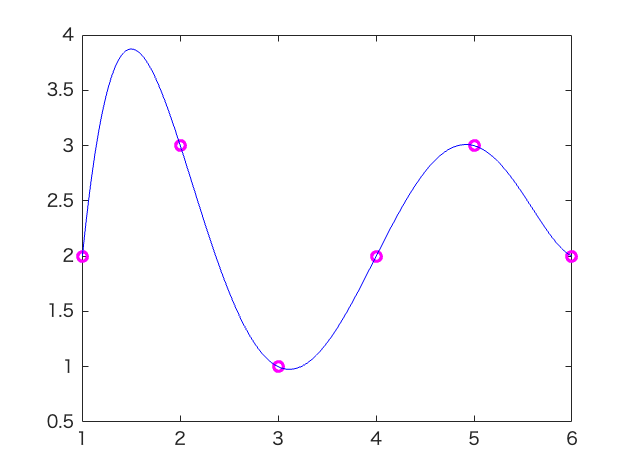

hold on
plot(xx, yy, 'b-')

To integrate function from 1 to 6 (analytical; exact)

format short
a = 1;
b = 6;
q = polyint(p5); % integrate polynomial equation (gives us the EXACT integration since this is a polynomial function)
Itrue = diff(polyval(q, [a, b])) % for relative value

Itrue = 11.7361

Compute using the Romberg function

% the given `romberg` function outputs an array
% the outputs are the exact same in Lec14 slides page 15
[I_romberg, ea, iter] = romberg(f, a, b, 0.5) % this gives the same value as `Itrue`

I_romberg = 11.7361

ea = 3.0272e-14

iter = 3

Compute using Gauss-Legendre Formulas

a1 = (b+a)/2;
a2 = (b-a)/2;

% MAIN VARIABLES WE NEED:
% x = (a1 + a2*x_d)
% dx = a2 .* dx_d [differentiate both sides]

% FROM f=@(x)
% WE TRANSFORM IT TO FIT THE CONTEXT (differentiate to 2nd order):
f2 = @(x_d) ...
     ( p5(1).*(a1 + a2*x_d).^5 + ...
     p5(2).*(a1 + a2*x_d).^4 + ...
     p5(3).*(a1 + a2*x_d).^3 + ...
     p5(4).*(a1 + a2*x_d).^2 + ...
     p5(5).*(a1 + a2*x_d) + ...
     p5(6) ) * ...
     a2;
% Q: Why multiply all with a2?
% A: From differentiation of `x`; from differentiation of both sides (Lec14 slides p.22)

% FOR THE POINTS…
% WE CHOOSE THE WEIGHTS (c0 and c1 [2 points] from table in Lec14 slides p.21)
c0 = 1; c1 = 1;
x0 = -1/sqrt(3); x1 = 1/sqrt(3);
I_2pts = (c0 * f2(x0)) + (c1 * f2(x1)) % the formula based off from Lec14 slides p.18

I_2pts = 14.6296

% WE CHOOSE THE WEIGHTS (c0, c1, and c2 [3 points] from table in Lec14 slides p.21)
c0 = 5/9; c1 = 8/9; c2 = 5/9;
x0 = -sqrt(3/5); x1 = 0; x2 = sqrt(3/5);
I_3pts = (c0 * f2(x0)) + (c1 * f2(x1)) + (c2 * f2(x2)) % the formula based off from Lec14 slides p.18

I_3pts = 11.7361

Compute using Adaptive Quadrature

I_quadadapt = quadadapt(f, a, b, 0.5) % OUR GIVEN FUNCTION

I_quadadapt = 11.7361

Compute using MATLAB's integral function

I_integral = integral(f, a, b)

I_integral = 11.7361

## Q2

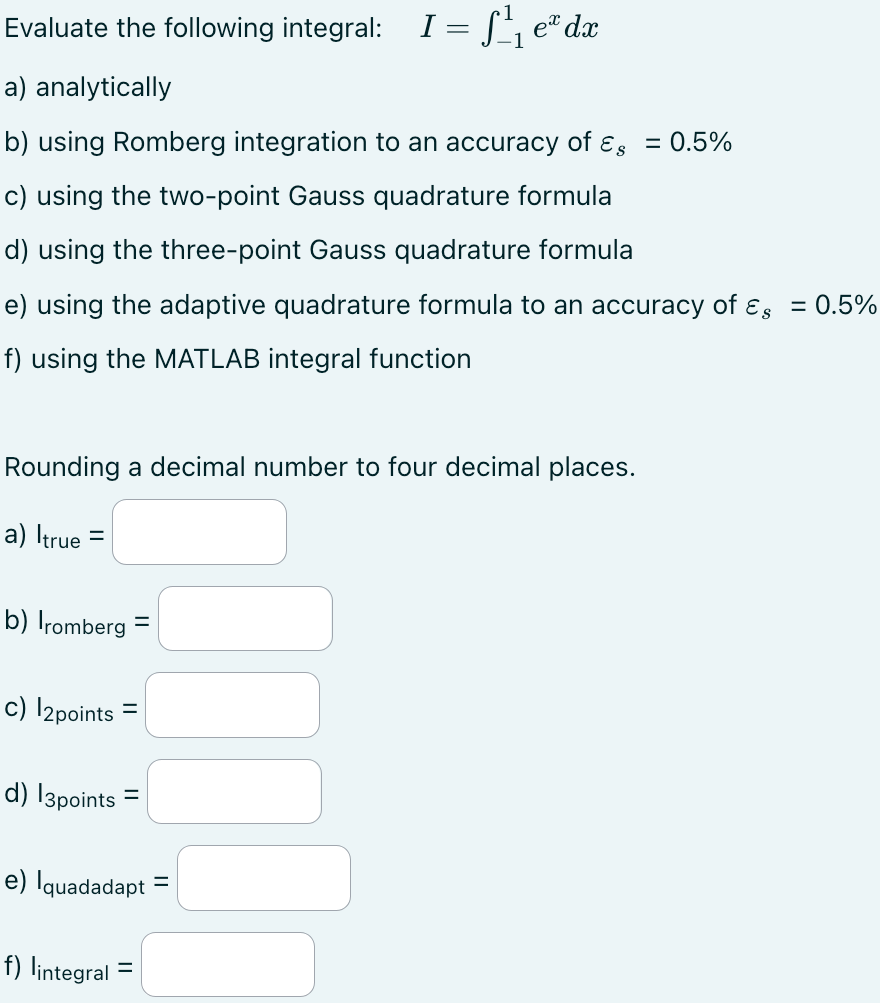

Data and the function

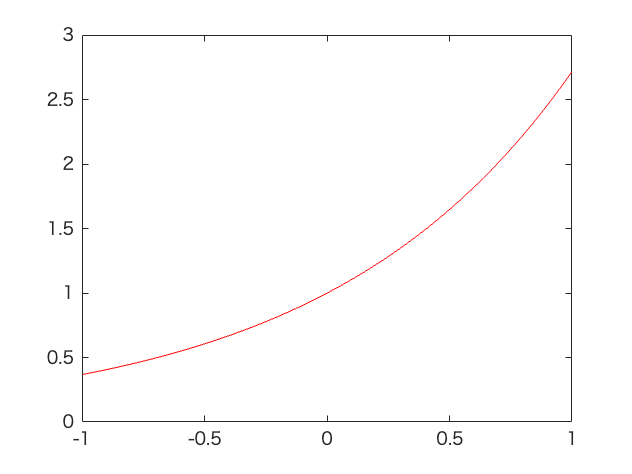

f = @(x) exp(x);
a = -1;
b = 1;
x = a : 0.01 : b;
y = f(x);
% PLOTTING
figure
plot(x, y, 'r-')

To integrate function from -1 to 1 (analytical; exact)

format short
Itrue = exp(b) - exp(a)

Itrue = 2.3504

Compute using the Romberg function

% the given `romberg` function outputs an array
% the outputs are the exact same in Lec14 slides page 15
[I_romberg, ea, iter] = romberg(f, a, b, 0.5) % this gives the same value as `Itrue`

I_romberg = 2.3505

ea = 0.0308

iter = 2

Compute using Gauss-Legendre Formulas *(shifts from -1 to 1; redundant because the integral range is already -1 to 1, but the answer is still correct)*

% SHIFTING
a1 = (b+a)/2;
a2 = (b-a)/2;

% MAIN VARIABLES WE NEED:
% x = (a1 + a2*x_d)
% dx = a2 .* dx_d [differentiate both sides; Lec14 p.22]

% *** We can actually start right here ***
% FROM f=@(x) exp(x)
% WE TRANSFORM IT TO FIT THE CONTEXT:
f2 = @(x_d) exp(a1 + a2 .* x_d) * a2;

% FOR THE POINTS…
% WE CHOOSE THE WEIGHTS (c0 and c1 [2 points] from table in Lec14 slides p.21)
c0 = 1; c1 = 1;
x0 = -1/sqrt(3); x1 = 1/sqrt(3);
I_2pts = (c0 * f2(x0)) + (c1 * f2(x1)) % the formula based off from Lec14 slides p.18

I_2pts = 2.3427

% WE CHOOSE THE WEIGHTS (c0, c1, and c2 [3 points] from table in Lec14 slides p.21)
c0 = 5/9; c1 = 8/9; c2 = 5/9;
x0 = -sqrt(3/5); x1 = 0; x2 = sqrt(3/5);
I_3pts = (c0 * f2(x0)) + (c1 * f2(x1)) + (c2 * f2(x2)) % the formula based off from Lec14 slides p.18

I_3pts = 2.3503

Compute using Adaptive Quadrature

I_quadadapt = quadadapt(f, a, b, 0.5) % OUR GIVEN FUNCTION

I_quadadapt = 2.3505

Compute using MATLAB's integral function

I_integral = integral(f, a, b)

I_integral = 2.3504